# Load and Format Data for Ovarian Targets

`[OvarianInputs, OvarianTargets] = LoadOvarian(Preview)` loads the ovarian dataset packaged with MATLAB and prepares and outputs the `OvarianInputs` and `OvarianTargets` tables. The optional argument `Preview `is a logical that enables the user to choose whether or not to preview data. The original dataset does not include row or column headers.

In the first section, we load `ovarian_dataset.mat` into two variables, ovarianInputs and ovarianTargets. These variables appear in our workspace.

 

We notice that `ovarianInputs` is a 100 x 216 double, and `ovarianTargets` is a 2 x 216 double. From the [doc](https://www.mathworks.com/help/matlab/ref/doc.html?searchHighlight=doc&s_tid=srchtitle_support_results_1_doc) function, we learn the dataset is representative of the ion intensity levels and diagnoses of 216 patients.  Each row in the `ovarianInputs` variable represents ion intensity levels for different ion intensity levels (the independent variable), and each column corresponds to a patient. Similarly, in `ovarianOutputs`, we see that each row represents a cancer or non-cancer diagnosis. 

To make the data structure more closely align to our intuitive graphical representations, We want the "Patients" to be the rows and the ion intensity levels to be the columns.To address this, we transpose the matrix so that patients become rows and features (measurements) become columns. This structure ensures that patient-specific trends and patterns are more intuitively represented and easier to analyze, directly impacting the effectiveness of our analysis and visualization efforts.

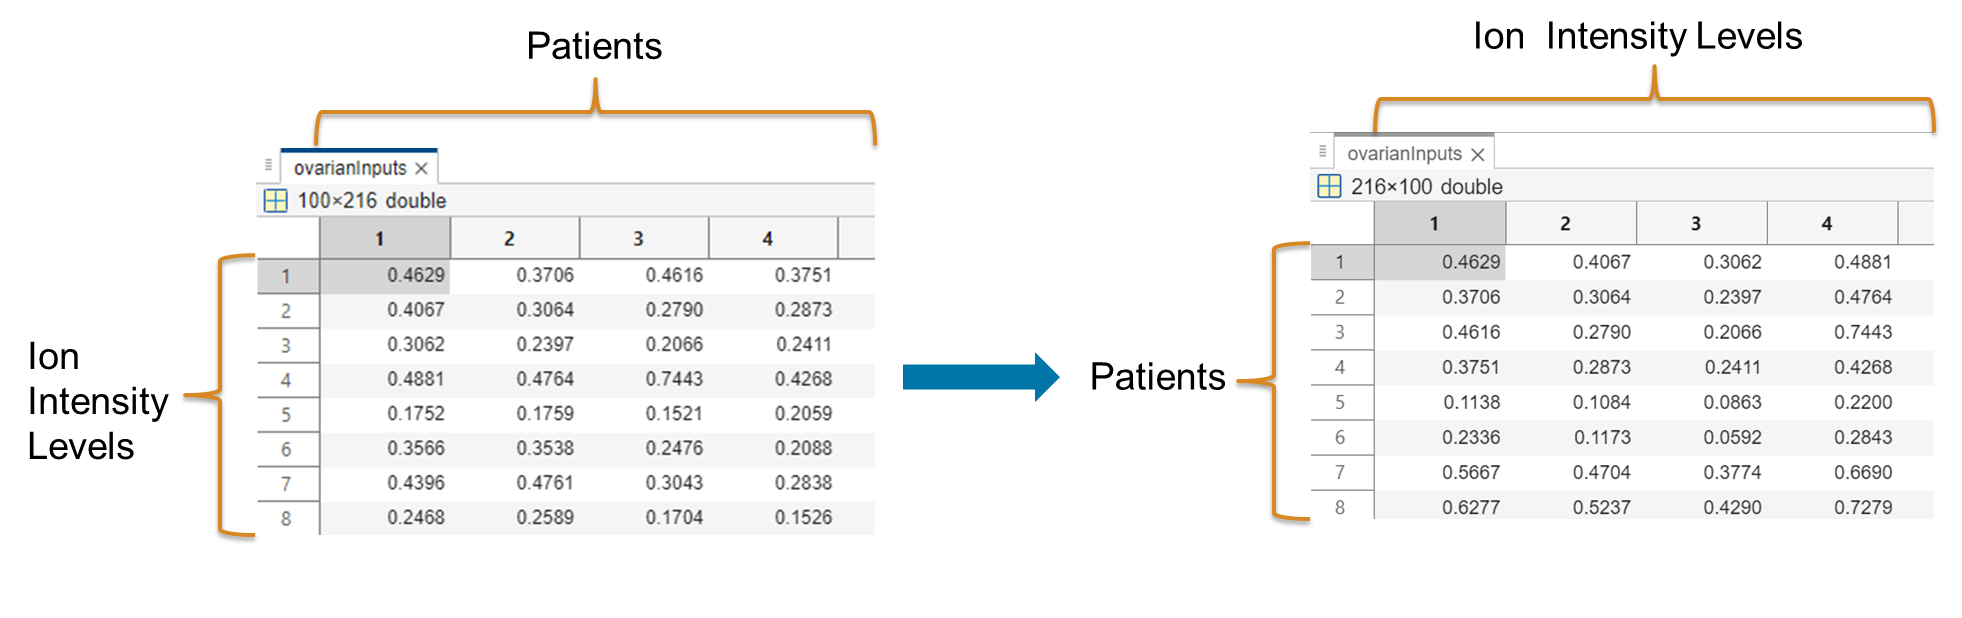

We use `array2table` to convert the two matrices loaded into the workspace into a table. 

Learn more about tables in the self-paced course, [Tables](https://matlabacademy.mathworks.com/details/tables/otmltab). With our data now in a table, we can add row names and column names to both tables. Tables are powerful in MATLAB. Consider exploring the [Organizing Tabular Data in MATLAB](https://matlabacademy.mathworks.com/details/organize-tabular-data-in-matlab/lpmlotd) learning path.

We name the tables `OvarianInputs`, and `OvarianTargets`. If you double-click on the `OvarianInputs` in the workspace to view the table, a new window will open. In this window, you will see the dataset along with summary statistics for each column. 

 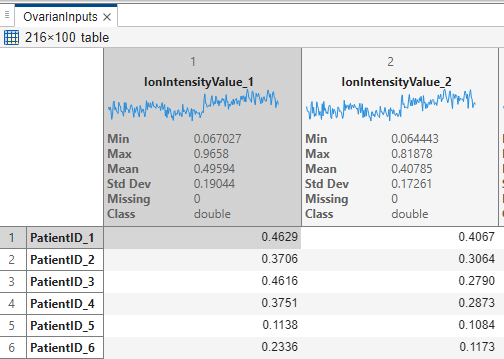

If you would like to preview the first 10 rows of the data, you can check the Preview data  box or set `Preview == 1` in your function call. Here is an example of what you will see with the dataset preview:

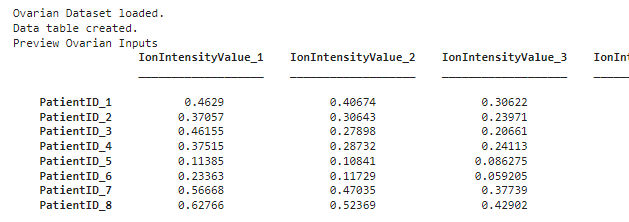

function [OvarianInputs, OvarianTargets] = LoadOvarian(Preview,Help)
arguments
    Preview (1,1) logical = false
    Help (1,1) logical = false
end
load ovarian_dataset.mat ovarianInputs ovarianTargets % Load two variables: ovarianTargets and ovarianInputs
disp("Ovarian Dataset loaded.")

## Create Data Tables

OvarianInputs = array2table(ovarianInputs'); % Convert and transpose ovarianInputs matrix to a table
OvarianTargets = array2table(ovarianTargets'); % Convert and transpose ovarianTargets matrix to a table

OvarianInputs.Properties.RowNames = strcat("PatientID_",string(1:height(OvarianInputs))); % Label the rows as 'Patient ID: 1', 'Patient ID: 2', etc.
OvarianInputs.Properties.VariableNames = strcat("IonIntensityValue_",string(1:width(OvarianInputs))); % Label the rows as 'Ion Intensity Values'
OvarianTargets.Properties.RowNames = strcat("PatientID_",string(1:height(OvarianTargets))); % Label the columns as 'Patient ID: 1', 'Patient ID: 2', etc.
OvarianTargets.Properties.VariableNames = ["Cancer","NoCancer"]; % Label the rows as 'Ion Intensity Values'
disp("Data table created.")

## Preview Data Tables

If you would like to preview the data tables, select the Preview checkbox.

if Preview == true % Display the first ten lines of each table if preview is selected
    disp("Preview Ovarian Inputs")
    head(OvarianInputs) % Display first 10 lines of OvarianInputs
    disp("Preview Ovarian Targets")
    head(OvarianTargets) % Display first 10 lines of OvarianTargets
end

## Display Help for Data

Open the [doc](https://www.mathworks.com/help/releases/R2025a/matlab/ref/doc.html?searchHighlight=doc&s_tid=doc_srchtitle) documentation to learn about the dataset.

if Help == true % Display the help section if Help is selected
    doc ovarian_dataset
end

end